layers = [ ...
    sequenceInputLayer(2)
    bilstmLayer(100,'OutputMode','last')
    fullyConnectedLayer(3)
    softmaxLayer
    classificationLayer
    ]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 2 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         3 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex


options = trainingOptions('adam', ...
    'MaxEpochs',150, ...
    'MiniBatchSize', 128, ...
    'InitialLearnRate', 0.0001, ...
    'GradientThreshold', 1, ...
    'ExecutionEnvironment',"auto",...
    'plots','training-progress', ...
    'Verbose',false);

YTrain = removecats(YTrain);

Unrecognized function or variable 'YTrain'.

YTest = removecats(YTest);

layers

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 2 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         3 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex


LSTM = trainNetwork(XTrainSD,YTrain,layers,options);


[preds, scores] = classify(LSTM,XTestSD);

LSTMAccuracy = sum(preds == YTest)/numel(YTest)*100

LSTMAccuracy = 60.6061

[confMat, order] = confusionmat(YTest, preds);
Precision = (confMat(1,1))/(sum(confMat(:,1)))

Precision = 0.5849

Recall = confMat(1,1)/sum(confMat(1,:))

Recall = 0.8611

F1 = 2*(Precision*Recall)/(Precision+Recall)

F1 = 0.6966



% save('TrainedSVM_mov','net','YTest','TestFeatures','YTrain','TrainFeatures');

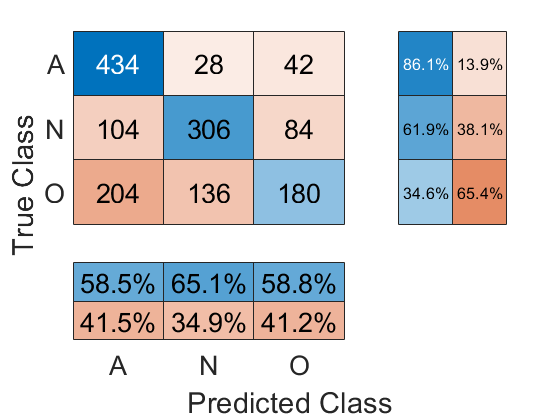


clc
close all
figure(1)
confusionchart(YTest,preds,'ColumnSummary','column-normalized',...
              'RowSummary','row-normalized','FontSize',20);

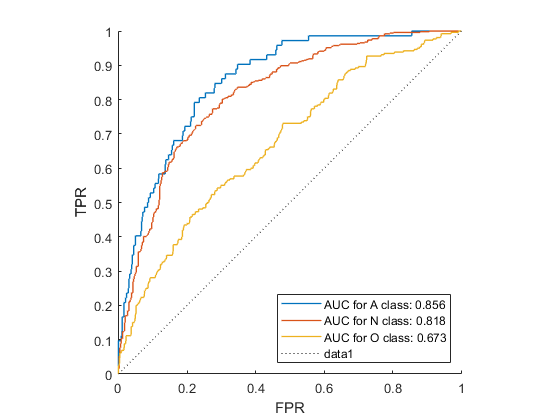

classNames = {'A','N','O'};
clf;
figure(2)
hold on
for i=1:3
    [xr, yr, ~, auc] = perfcurve(YTest,scores(:, i), classNames{i});
    plot(xr, yr, 'linewidth', 1)
    legends{i} = sprintf('AUC for %s class: %.3f', classNames{i}, auc);
end

legend(legends, 'location', 'southeast')
line([0 1], [0 1], 'linestyle', ':', 'color', 'k');
xlabel('FPR'), ylabel('TPR')
% title('ROC for ECG Classification (LSTM + MoV)')
axis square
hold off

save('movLSTM','LSTM','YTest','XTestSD','YTrain','XTrainSD');